**1**. Implementieren Sie ein MATLAB-Skript, das für ein gegebenes Eingangsbild sämtliche Schritte der Hough-Transformation visualisiert, d.h. insbesondere das binäre **Kantenbild**, den **Hough-Raum**, und die in das Originalbild projizierten **Geradensegmente**. Falls nötig, finden Sie in der MATLAB Hilfe ein Code-Beispiel, auf dem Sie aufbauen können.

实现一个MATLAB脚本，将给定输入图像的Hough变换的所有步骤可视化，即特别是二进制边缘图像、Hough空间和投射到原始图像的直线段。如果有必要，你可以在MATLAB的帮助中找到一个代码例子来进行借鉴。

MATLAB bietet Funktionen zur Durchführung einer Hough-Transformation für gerade Linienelemente. Diese Funktionen sind:

`[H, theta, rho] = hough(BW) - `Berechnet die Hough-Transformierte aus einem Binärbild.

`peaks = houghpeaks(H, numpeaks) - `Sucht Höchstwerte im Hough-Raum

`lines = houghlines(BW, theta, rho, peaks) - `Bildet mit Hilfe der gefundenen Geraden und des Binärbilds zugehörige Geradensegmente

binäres Kantenbild:

% I1 = imread('../Bilder/Test_Bild1.png');
% I2 = imread('../Bilder/Test_Bild2.png');
% I3 = imread('../Bilder/Test_Bild3.png');
% I4 = imread('../Bilder/Test_Bild4.png');
% I5 = imread('../Bilder/Test_Bild5.png');
% I6 = imread('../Bilder/Test_Bild6.png');
% I7_1 = imread('../Bilder/Test_Bild7_1.png');
% I7_2 = imread('../Bilder/Test_Bild7_2.png');
% I7_3 = imread('../Bilder/Test_Bild8.png');
% BW1 = im2gray(I1);
% BW2 = im2gray(I2);
% BW3 = im2gray(I3);
% BW4 = im2gray(I4);
% BW5 = im2gray(I5);
% BW6 = im2gray(I6);
% BW7_1 = im2gray(I7_1);
% BW7_2 = im2gray(I7_2);
% BW7_3 = im2gray(I7_3);
% edge1 = edge(BW1,"canny");
% edge2 = edge(BW2,"canny");
% edge3 = edge(BW3,"canny");
% edge4 = edge(BW4,"canny");
% edge5 = edge(BW5,"canny");
% edge6 = edge(BW6,"canny");
% edge7_1 = edge(BW7_1,"canny");
% edge7_2 = edge(BW7_2,"canny");
% edge7_3 = edge(BW7_3,"canny");
% % imshow(edge7_1);
% % imshow(edge7_2);
% imshow(edge7_3);
% % imshowpair(edge1,edge2,'montage');
% % imshowpair(edge3,edge4,'montage');
% % imshowpair(edge5,edge6,'montage');
% Input_path = '../Bilder/';
% namelist = dir(strcat(Input_path,'*.png'));  %获得文件夹下所有的 .jpg图片
% len = length(namelist);
% for i = 14:(len)
%     name=namelist(i).name;  %namelist(i).name; %这里获得的只是该路径下的文件名
%     I=imread(strcat(Input_path, name)); %图片完整的路径名
%     B = im2gray(I);
% %     K2=wiener2(B,[5 5]); %对图片进行去噪处理
%     K2 = medfilt2(B);
%     BW = edge(K2,"canny");
%     [H,theta,rho] = hough(BW);
%     P = houghpeaks(H,5,'threshold',ceil(0.4*max(H(:)))); %寻找矩阵中前5个大于最大值0.3倍的峰值，并按行、列索引转换成实际坐标，并在矩阵图像中标出峰值位置。
%     lines = houghlines(BW,theta,rho,P,'FillGap',5,'MinLength',7); %当两条线的距离小于5时，houghlines函数就会将这两条线合并成一条线，否则就保存。
%     %使用 houghlines 函数查找图像中的线条。
% %     imwrite(BW,"BW.png")
% %     hold on
% %     imwrite(imadjust(rescale(H)),"H.png")
% %     figure
% %     x = theta(P(:,2));
% %     y = rho(P(:,1));
% %     plot(x,y,'s','color','black');
%     
% %     将检测到的直线和端点显示出来。
% %     imshow(BW), hold on
% %     max_len = 0;
% %     for k = 1:length(lines)
% %        xy = [lines(k).point1; lines(k).point2];
% %        plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
% %     
% %        % Plot beginnings and ends of lines
% %        plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
% %        plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
% %     
% %        % Determine the endpoints of the longest line segment
% %        len = norm(lines(k).point1 - lines(k).point2);
% %        if ( len > max_len)
% %           max_len = len;
% %           xy_long = xy;
% %        end
% %     end
%     % highlight the longest line segment
% %     plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','black');
% %     subplot(2,1,1);
% %     RI = imref2d(size(BW));
% %     imshow(BW,'InitialMagnification','fit')
% %     title(i-3);
% %     subplot(2,1,2);
% %     RI = imref2d(size(I));
% %     RI.XWorldLimits = [-90 90];
% %     RI.YWorldLimits = [-1000 1000];
%     imshow(imadjust(rescale(H)),'XData',theta,'YData',rho,'InitialMagnification','fit');
% %     RA = imref2d(size(BW),0.2,0.2);
% %     RB = imref2d(size(H),0.2,0.2);
% %     imshowpair(BW,RA, imadjust(rescale(H)),RB,"montage");
%     xlabel('\theta (degrees)') 
%     ylabel('\rho')
%     title(i-2);%图片的显示
%     axis on
%     axis normal
%     hold on
%     colormap(gca,hot)
% %     set(gca,'xaxislocation','top');
% %     K2=wiener2(I,[5 5]); %对图片进行去噪处理
% %     imwrite(K2,[Output_path,'wie',int2str(i),'.jpg']); %完整的图片存储的路径名  并将整形的数字转换成字符串                                              
% end

Matlab example

% I = imread('circuit.tif');
% rotI = imrotate(I,33,'crop');
% imshow(rotI);
% BW = edge(rotI,'canny');
% imshow(BW);
% [H,theta,rho] = hough(BW);
% figure
% imshow(imadjust(rescale(H)),[],...
%        'XData',theta,...
%        'YData',rho,...
%        'InitialMagnification','fit');
% xlabel('\theta (degrees)')
% ylabel('\rho')
% axis on
% axis normal 
% hold on
% colormap(gca,hot)

- peaks = houghpeaks(H, numpeaks, Name, Value)

- H: Hough transform matrix

- numpeaks: Maximum number of peaks to identify 指定要识别的最大峰值个数

- Threshold: Minimum value to be considered a peak: 0.5*max(H(:)) (default) 被视为峰值的最小值，指定为非负数。

- NHoodSize: Size of suppression neighborhood 隐藏邻域的大小，指定为由正奇数组成的二元素向量。*隐藏邻域*是每个峰值周围的邻域，在识别出峰值后，该域内的值会设置为零。`NHoodSize` 的默认值为大于或等于 `size(H)/50` 的最小奇数值。`NHoodSize` 的维数必须小于 Hough 变换矩阵 [`H`](https://ww2.mathworks.cn/help/images/ref/houghpeaks.html?searchHighlight=houghpeaks&s_tid=srchtitle_houghpeaks_1#buw9d0p-1-H) 的大小。

% P_1 = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
% P_2 = houghpeaks(H,6,'threshold',ceil(0.3*max(H(:))));
% x_1 = theta(P_1(:,2));
% y_1 = rho(P_1(:,1));
% plot(x_1,y_1,'s','color','yellow');
% x_2 = theta(P_2(:,2));
% y_2 = rho(P_2(:,1));
% plot(x_2,y_2,'s','color','red');

Hough-Raum:

% [H, theta, rho] = hough(I);
% peaks = houghpeaks(H, numpeaks)
% lines = houghlines(BW, theta, rho, peaks)

in das Originalbild projizierte Geradensegmente:

Testen Sie die grundlegende Funktionsweise Ihres Programms anhand der Bilderserie „Test_Bild....png“. Versuchen Sie dabei die einzelnen Teilergebnisse und deren Zustandekommen nachzuvollziehen.

Recherchieren Sie die Funktionsweise der nachfolgend aufgelisteten Parameter und untersuchen Sie deren Einfluss auf das Ergebnis:

a.    Eigenschaften des Canny-Filters

Canny 方法与其他边缘检测方法的不同之处在于，它使用两种不同阈值（用于检测强边缘和弱边缘），并且仅当弱边缘连通到强边缘时才在输出中包括弱边缘。因此，这种方法不太可能受到噪声的影响，更可能检测到真正的弱边缘。

b.    Auflösung von rho und theta

c.    Anzahl und Schwellwert der zu findenden Maximalwerte im Hough-Raum

d.    Größe der Nachbarschaft, in der weitere Extremwerte unterdrückt werden 抑制进一步极端值的邻域的大小

e     Die Mindestlänge und maximale Lückengröße zur Bildung der Geradensegmente 形成直线段的最小长度和最大间隙尺寸

Diskutieren Sie den Effekt der einzelnen Parameter! 

**2**. Versuchen Sie nun, sämtliche Kanten im Bild „Platte1.png“ als Geradensegmente zu erkennen. Welche Segmente bereiten besondere Schwierigkeiten? Warum?

binäres Kantenbild:

Platte1 = imread('../Bilder/Platte2.png');
BW_Platte1 = im2gray(Platte1);
edge_Platte1 = edge(BW_Platte1,"canny",0.1);
% imshow(edge_Platte1);
% imshowpair(BW_Platte1, edge_Platte1,'montage');
% montage(Platte1)
[H1,theta1,rho1] = hough(edge_Platte1);
P1 = houghpeaks(H1,20,'threshold',ceil(0.4*max(H1(:)))); %寻找矩阵中前5个大于最大值0.3倍的峰值，并按行、列索引转换成实际坐标，并在矩阵图像中标出峰值位置。
lines1 = houghlines(edge_Platte1,theta1,rho1,P1,'FillGap',15,'MinLength',1); %当两条线的距离小于5时，houghlines函数就会将这两条线合并成一条线，否则就保存。
% imshow(imadjust(rescale(H1)),'XData',theta1,'YData',rho1,'InitialMagnification','fit');

% xlabel('\theta (degrees)') 
% ylabel('\rho')
% % title(i-2);%图片的显示
% axis on
% axis normal
% hold on
% colormap(gca,hot)

Hough-Raum:

in das Originalbild projizierte Geradensegmente:

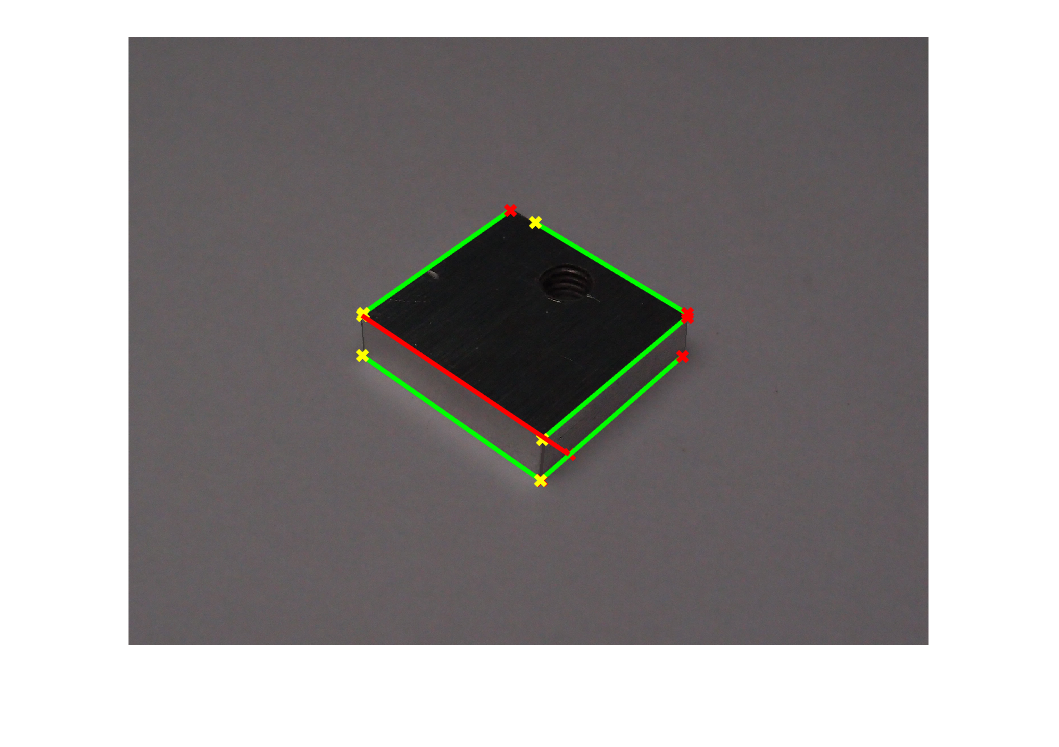

imshow(Platte1), hold on
max_len = 0;
for k = 1:length(lines1)
   xy = [lines1(k).point1; lines1(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines1(k).point1 - lines1(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
% highlight the longest line segment
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','red');

**Bonus:**

Wenden Sie Ihr in Aufgabe 2 angepasstes Skript zunächst ohne weitere Veränderungen auf das Bild „Platte2.png“ an. Diskutieren Sie das Ergebnis und schlagen Sie möglichst begründet Parameteränderungen vor, mit denen erneut sämtliche Geradensegmente hervorgehoben werden können.